# Photoluminescence: data analysis

## Load data

clear;
RhoData = ParsePLdata('rhodamine', 'photonE');  % Rhodamine

Temps = 10:10:290;
RubyData = cell(numel(Temps),1);    % Ruby
for it = 1:numel(Temps)
    RubyData{it} = ParsePLdata('ruby', Temps(it), 'photonE');
end

RubyRoomData = ParsePLdata('rubyRtemp', 'photonE');

## Define loss function for fitting

function loss = peak_sensitive_loss(yhat, y)
    delta = max(y) * 1e-3;
    loss = mean(((yhat - y).^2) ./ (abs(y) + delta) .* (y>300 | (y<300 & yhat>300)));
end
loss_func = @peak_sensitive_loss;

## Fit Rhodamine Data to 3-level effective model (single Lorentzian)

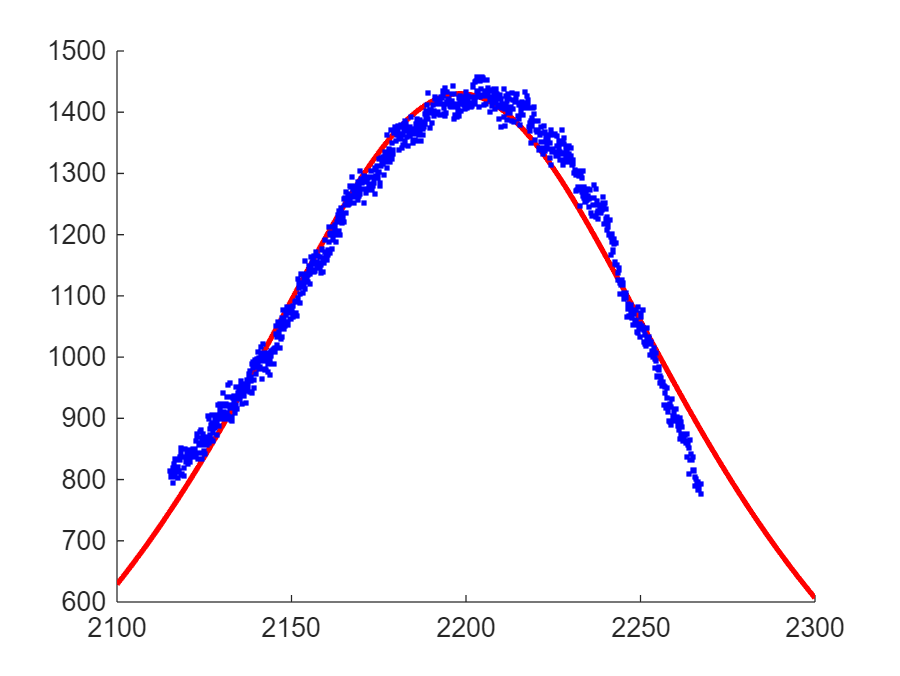

% photon energy range
Erange = [2100, 2300];
Energy = linspace(Erange(1), Erange(2), 1000);

% lower and upper bounds of fitting parameters
LowerBound = [1e3, -5, 2150];
UpperBound = [1e6, 3, 2250];
    
% choose data near the peaks
Idx = RhoData(:,1) > Erange(1) & RhoData(:,1) < Erange(2);
E_data = RhoData(Idx,1);
I_data = RhoData(Idx,2);

% make parameter bounds and loss function into a single struct variable
options.lb = LowerBound;
options.ub = UpperBound;
options.loss_type = loss_func;
    
% define fitting curve
FitModel = @(Params, Energies) Spec_3lev(Params(1), power(10, Params(2)), Params(3), Energies);
    
% iterate to find best fit
best_loss = Inf;
for it = 1:3
    options.rng_seed = it;          % Try different seeds
    Params0 = rand(1,3) .* (UpperBound - LowerBound) + LowerBound;      % try different initial parameters
    [params_i, loss_hist_i] = de_curve_fit(FitModel, E_data, I_data, Params0, options);     % differential evolution fitting
    if loss_hist_i(end) < best_loss
        best_loss = loss_hist_i(end);
        FitParams = params_i;
        loss_history = loss_hist_i;
    end
end
    
I0 = FitParams(1);
Linewidth = power(10, FitParams(2));
Ecen = FitParams(3);
    
% plot
figure;
hold on;
I_fit = Spec_3lev(I0, Linewidth, Ecen, Energy);
plot(Energy, I_fit, 'color', 'red', 'LineWidth', 2);
plot(E_data, I_data, '.', 'color', 'blue');
hold off;

    
% show fitted parameters
disp(['Loss = ', sprintf('%.4g', best_loss)]);

Loss = 1.151


disp(['I0 = ', sprintf('%.4g', I0)]);

I0 = 1.247e+05


disp(['Linewidth = ', sprintf('%.4g', Linewidth(1))]);

Linewidth = 174.4


disp(['Ecen = ', sprintf('%.4g', Ecen)]);

Ecen = 2198


## Fit Rhodamine Data to 4-level effective model (double Lorentzian)

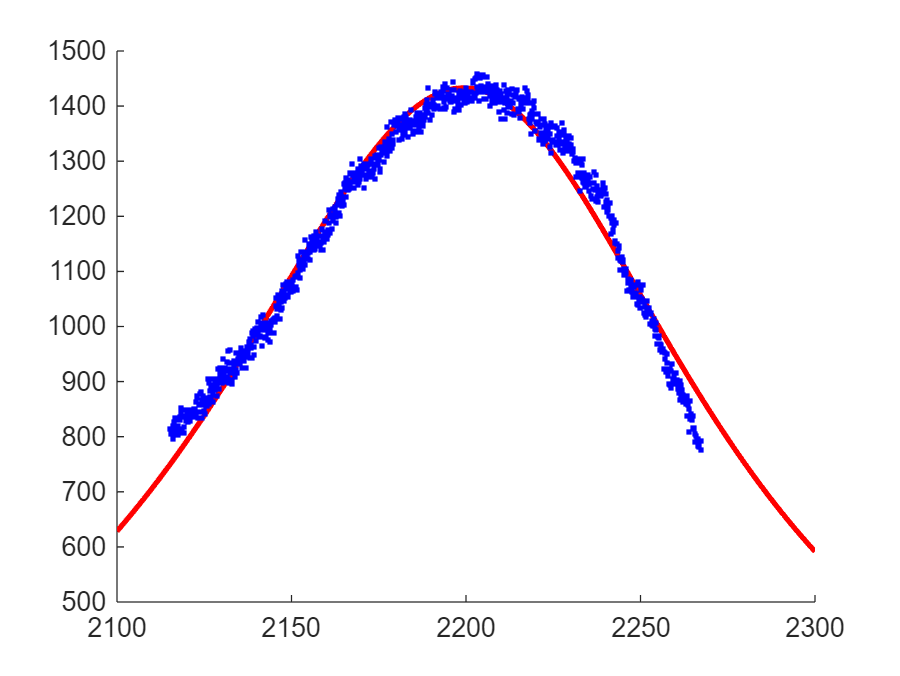

% photon energy range
Erange = [2100, 2300];
Energy = linspace(Erange(1), Erange(2), 1000);

% lower and upper bounds of fitting parameters
LowerBound = [10, 0, -5, -5, 1e-2, 2150];
UpperBound = [1e4, 10, 3, 3, 1e2, 2250];

% fit data
T = 300;    % temperature
    
% choose data near the peaks
Idx = RhoData(:,1) > Erange(1) & RhoData(:,1) < Erange(2);
E_data = RhoData(Idx,1);
I_data = RhoData(Idx,2);

% make parameter bounds and loss function into a single struct variable
options.lb = LowerBound;
options.ub = UpperBound;
options.loss_type = loss_func;
    
% define fitting curve
FitModel = @(Params, Energies) Spec_4lev(Params(1), Params(2), [power(10, Params(3)), power(10, Params(4))], Params(5), Params(6), T, Energies);
    
% iterate to find best fit
best_loss = Inf;
for it = 1:3
    options.rng_seed = it;          % Try different seeds
    Params0 = rand(1,6) .* (UpperBound - LowerBound) + LowerBound;      % try different initial parameters
    [params_i, loss_hist_i] = de_curve_fit(FitModel, E_data, I_data, Params0, options);     % differential evolution fitting
    if loss_hist_i(end) < best_loss
        best_loss = loss_hist_i(end);
        FitParams = params_i;
        loss_history = loss_hist_i;
    end
end
    
I0 = FitParams(1);
TransAmpR = FitParams(2);
Linewidth = [power(10, FitParams(3)), power(10, FitParams(4))];
Delta = FitParams(5);
E1 = FitParams(6);
    
% plot
figure;
hold on;
I_fit = Spec_4lev(I0, TransAmpR, Linewidth, Delta, E1, T, Energy);
plot(Energy, I_fit, 'color', 'red', 'LineWidth', 2);
plot(E_data, I_data, '.', 'color', 'blue');
hold off;

    
% show fitted parameters
disp(['Temperature = ', sprintf('%d', T), ' K']);

Temperature = 300 K


disp(['Loss = ', sprintf('%.4g', best_loss)]);

Loss = 0.9857


disp(['I0 = ', sprintf('%.4g', I0)]);

I0 = 1e+04


disp(['d_{20}/d_{10} = ', sprintf('%.4g', TransAmpR)]);

d_{20}/d_{10} = 9.124


disp(['Linewidths = [', sprintf('%.4g', Linewidth(1)), ', ', sprintf('%.4g', Linewidth(2)) ']']);

Linewidths = [165.2, 166.8]


disp(['Delta = ', sprintf('%.4g', Delta)]);

Delta = 51.81


disp(['E1 = ', sprintf('%.4g', E1)]);

E1 = 2150


## Fit Ruby Data to 4-level effective model (double Lorentzian)

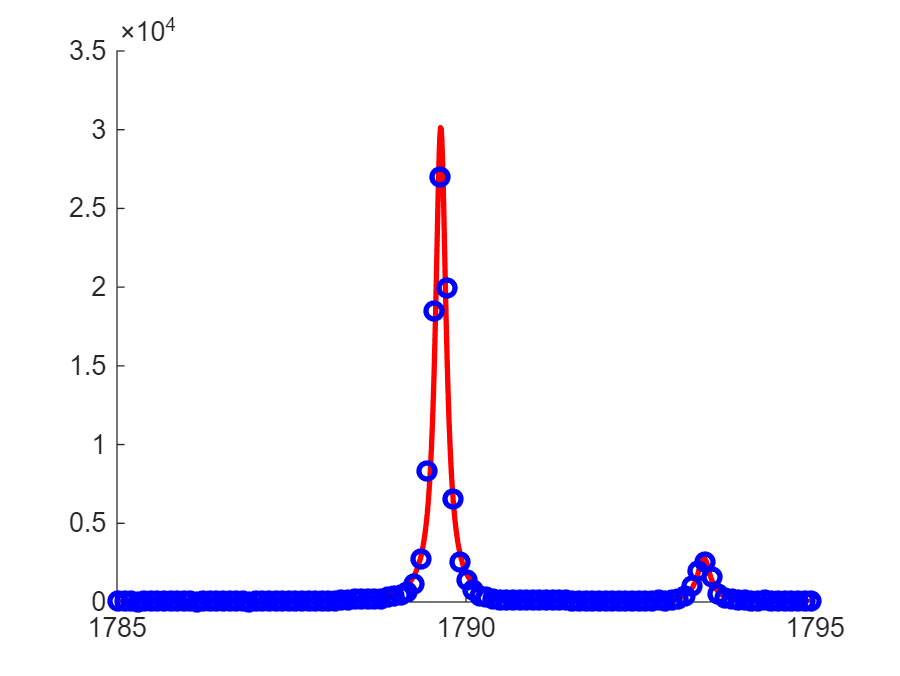

Temperature = 10 K


Loss = 49.98


I0 = 2800


d_{20}/d_{10} = 2.994


Linewidths = [0.1855, 0.2272]


Delta = 3.768


E1 = 1790


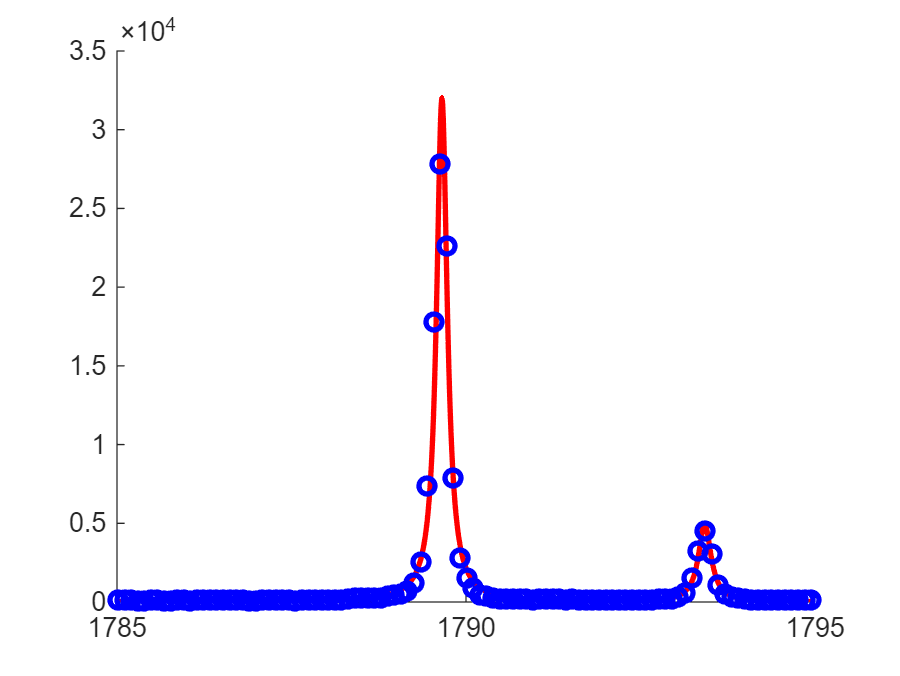

Temperature = 20 K


Loss = 43.87


I0 = 2960


d_{20}/d_{10} = 1.274


Linewidths = [0.1849, 0.2209]


Delta = 3.765


E1 = 1790


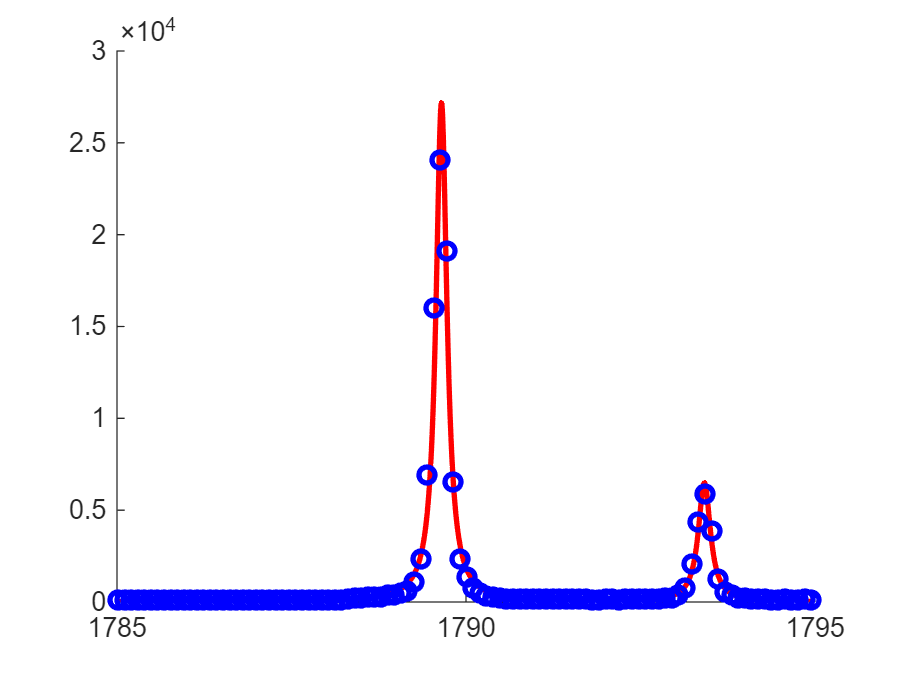

Temperature = 30 K


Loss = 39.89


I0 = 2589


d_{20}/d_{10} = 1.065


Linewidths = [0.1902, 0.2111]


Delta = 3.767


E1 = 1790


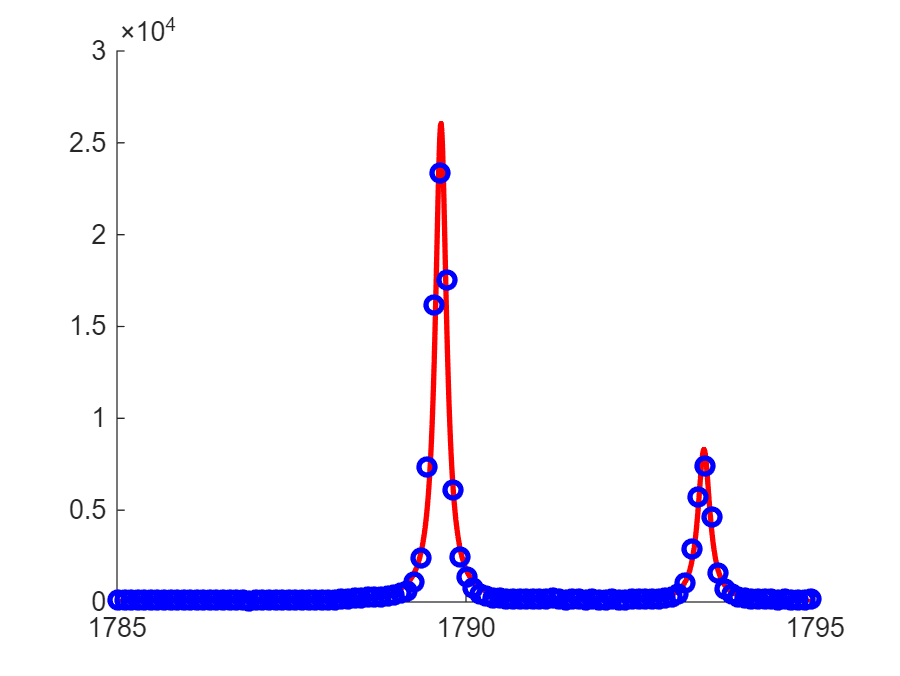

Temperature = 40 K


Loss = 39.45


I0 = 2533


d_{20}/d_{10} = 1.008


Linewidths = [0.1942, 0.2076]


Delta = 3.768


E1 = 1790


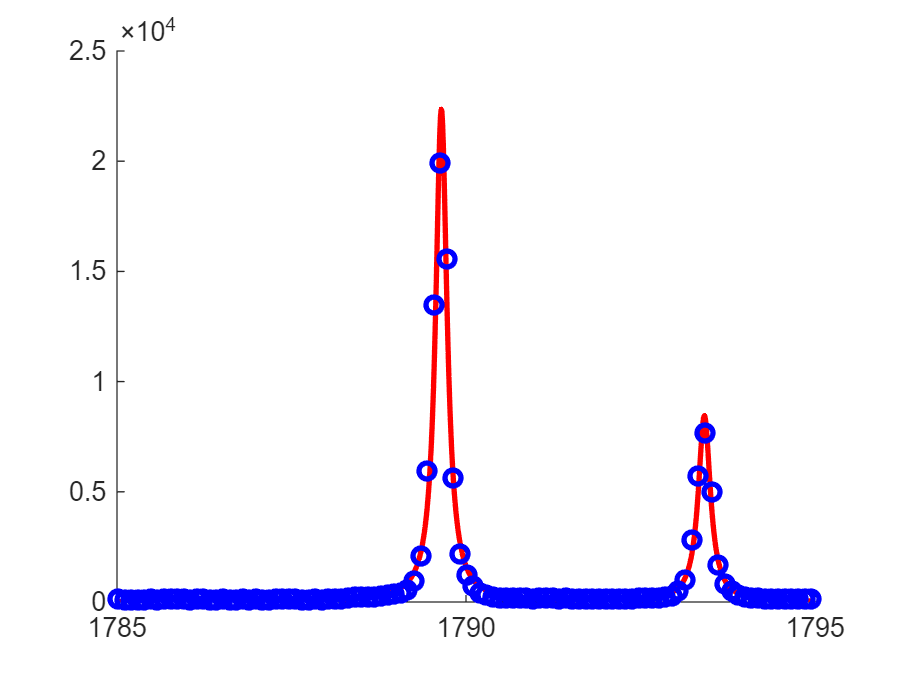

Temperature = 50 K


Loss = 30.66


I0 = 2208


d_{20}/d_{10} = 0.9836


Linewidths = [0.1974, 0.2109]


Delta = 3.768


E1 = 1790


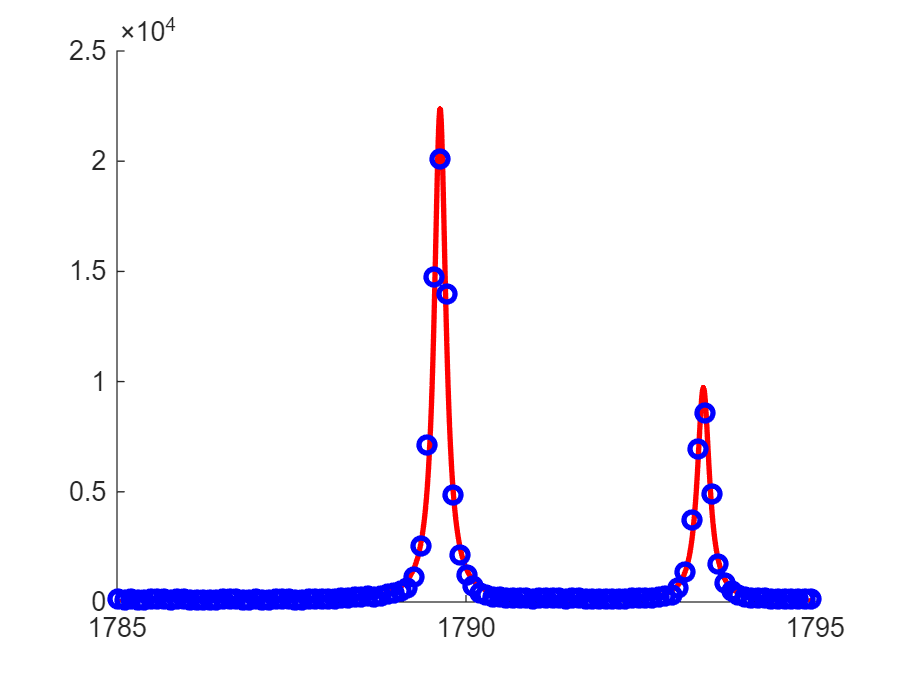

Temperature = 60 K


Loss = 27.68


I0 = 2259


d_{20}/d_{10} = 0.968


Linewidths = [0.2016, 0.2098]


Delta = 3.772


E1 = 1790


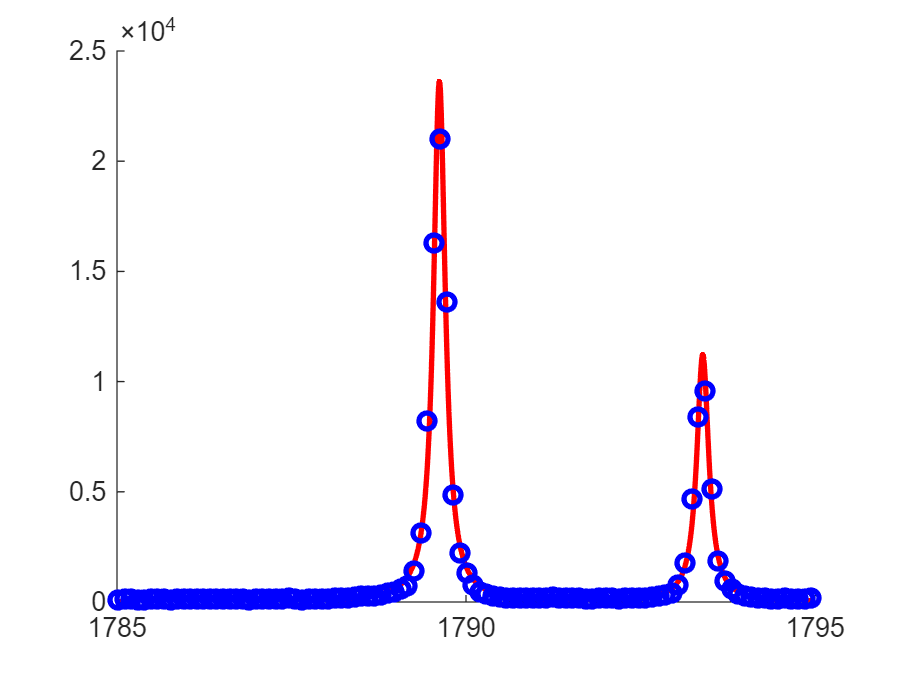

Temperature = 70 K


Loss = 25.03


I0 = 2431


d_{20}/d_{10} = 0.9485


Linewidths = [0.2054, 0.2082]


Delta = 3.773


E1 = 1790


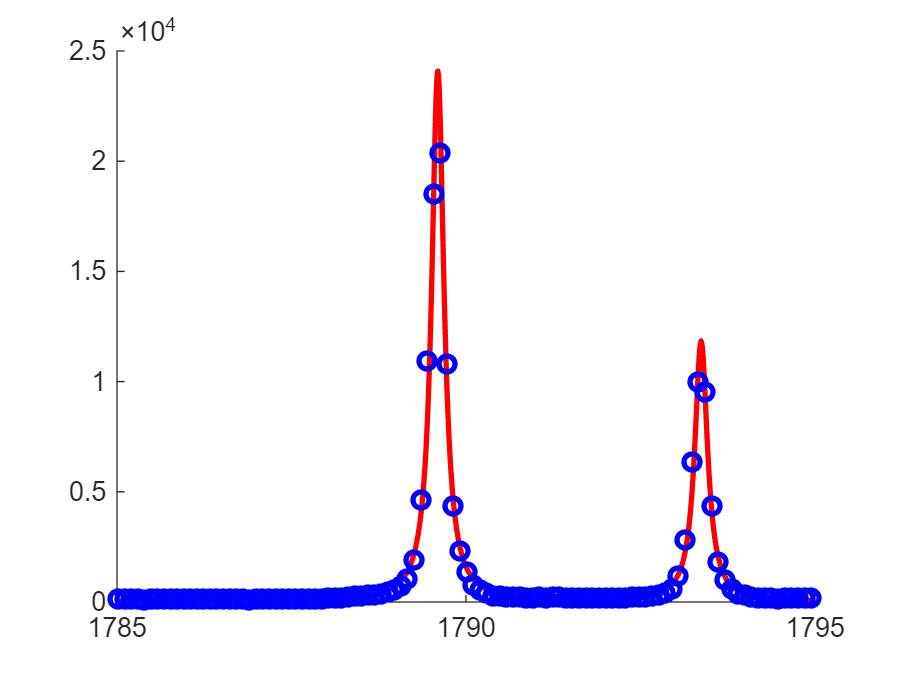

Temperature = 80 K


Loss = 20.75


I0 = 2588


d_{20}/d_{10} = 0.9376


Linewidths = [0.2149, 0.2226]


Delta = 3.772


E1 = 1790


Temperature = 90 K


Loss = 20.75


I0 = 2588


d_{20}/d_{10} = 0.9095


Linewidths = [0.2149, 0.2226]


Delta = 3.772


E1 = 1790


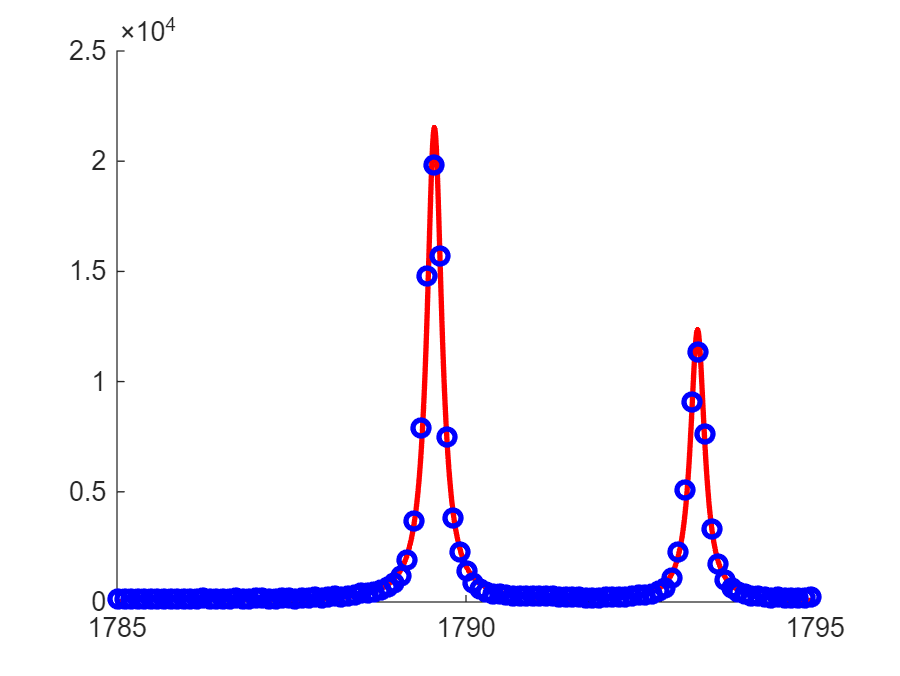

Temperature = 100 K


Loss = 13.79


I0 = 2781


d_{20}/d_{10} = 0.9217


Linewidths = [0.2583, 0.2471]


Delta = 3.77


E1 = 1790


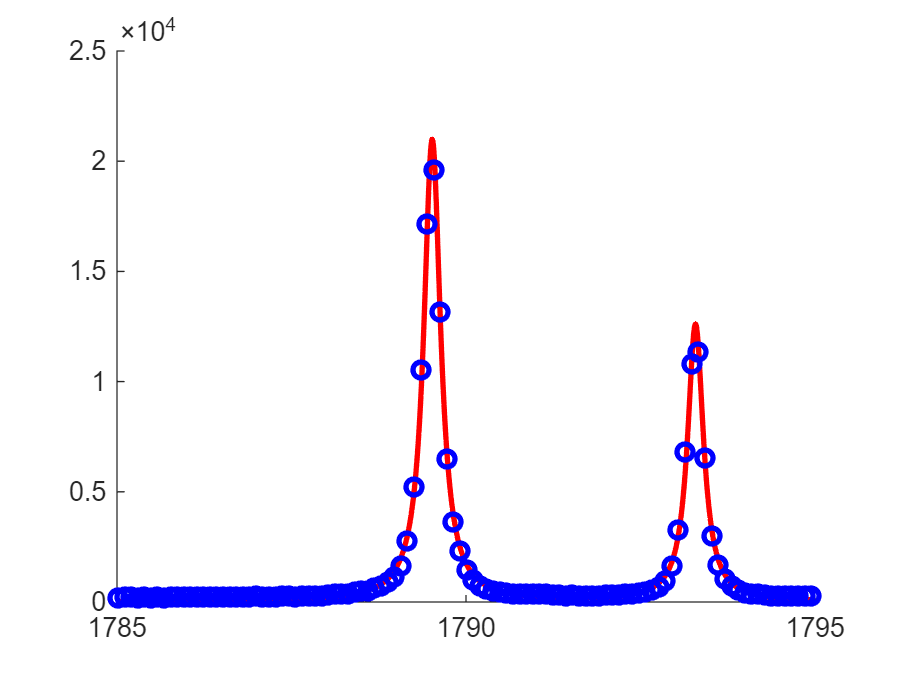

Temperature = 110 K


Loss = 16.85


I0 = 3048


d_{20}/d_{10} = 0.9199


Linewidths = [0.2904, 0.2752]


Delta = 3.772


E1 = 1790


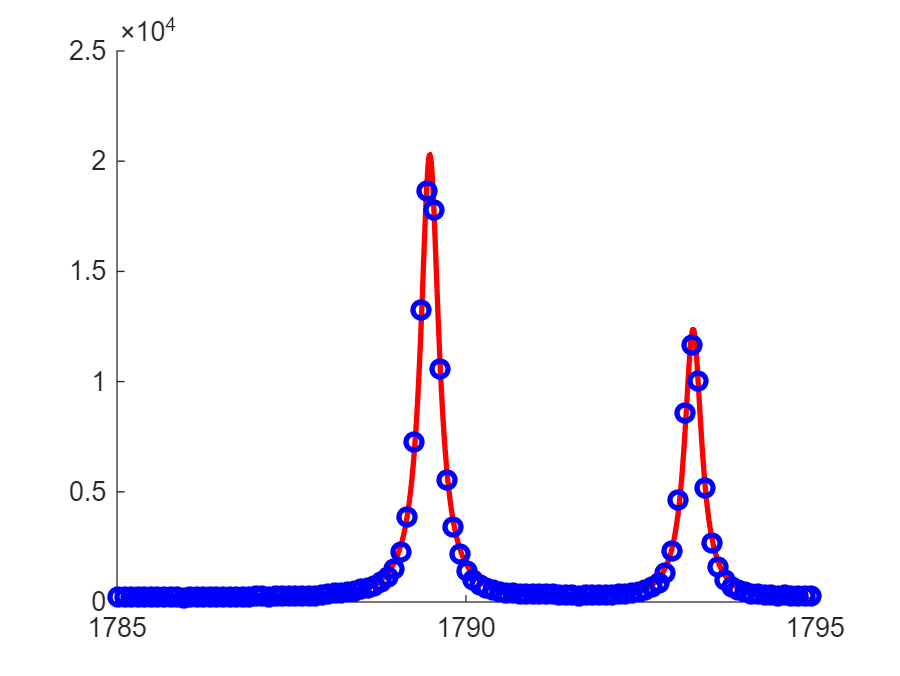

Temperature = 120 K


Loss = 18.88


I0 = 3196


d_{20}/d_{10} = 0.9083


Linewidths = [0.315, 0.2962]


Delta = 3.772


E1 = 1789


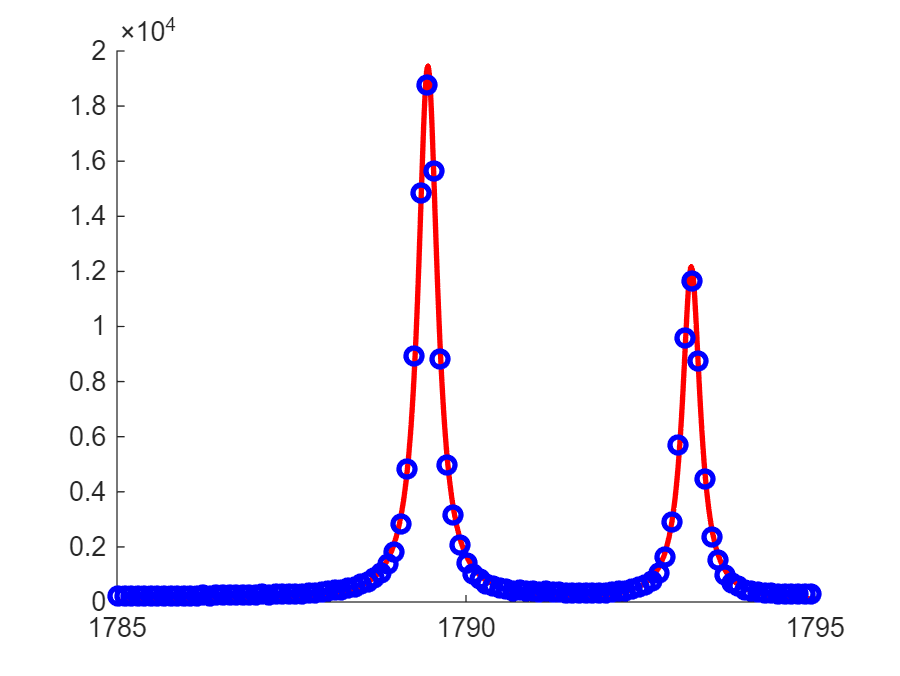

Temperature = 130 K


Loss = 17.28


I0 = 3265


d_{20}/d_{10} = 0.8972


Linewidths = [0.3359, 0.3093]


Delta = 3.774


E1 = 1789


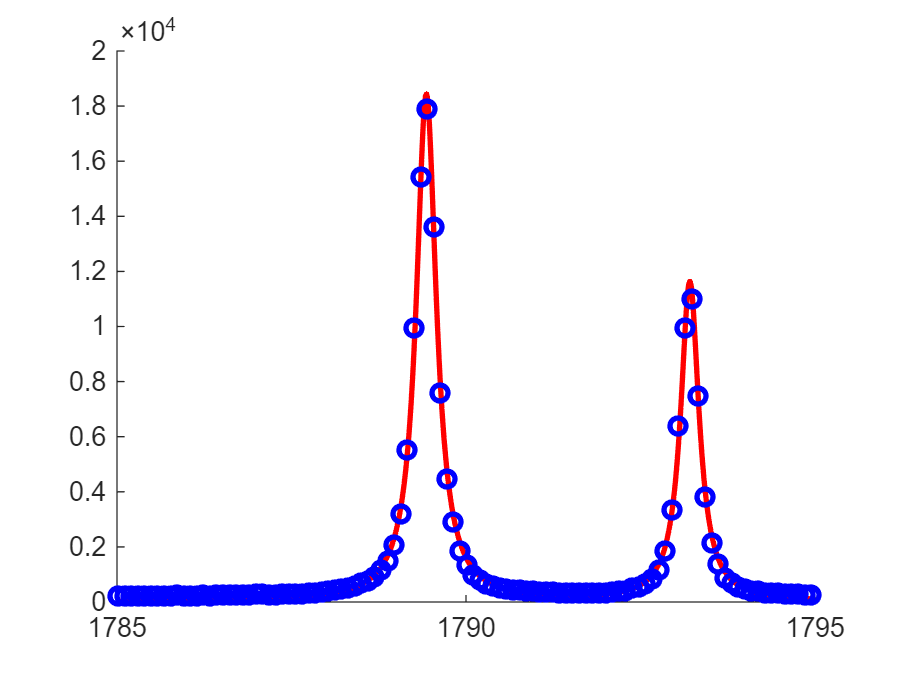

Temperature = 140 K


Loss = 17.82


I0 = 3215


d_{20}/d_{10} = 0.8872


Linewidths = [0.349, 0.3191]


Delta = 3.775


E1 = 1789


Temperature = 150 K


Loss = 17.82


I0 = 3215


d_{20}/d_{10} = 0.878


Linewidths = [0.349, 0.3191]


Delta = 3.775


E1 = 1789


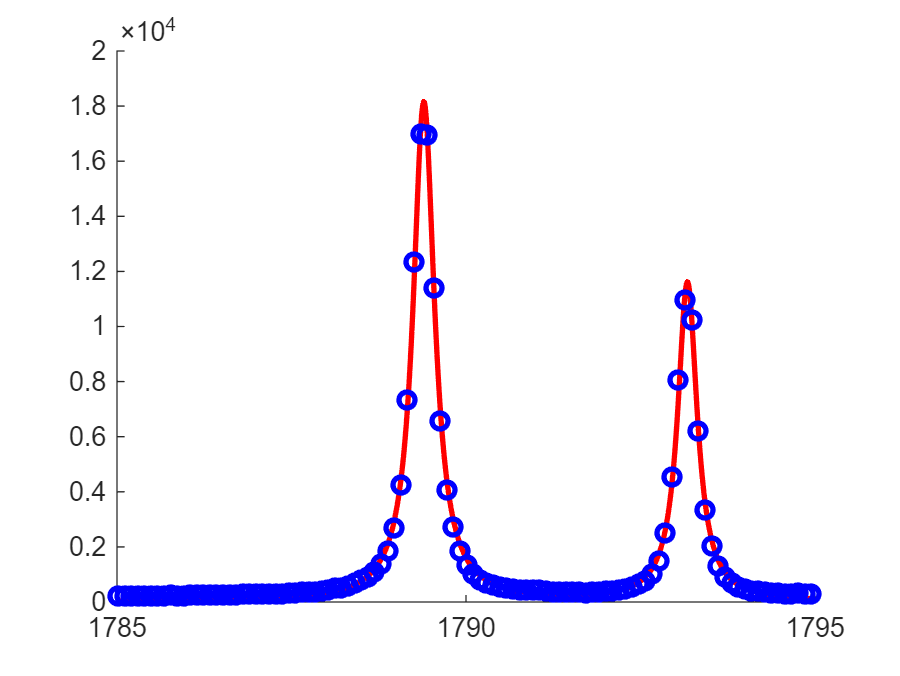

Temperature = 160 K


Loss = 20.43


I0 = 3380


d_{20}/d_{10} = 0.8728


Linewidths = [0.3725, 0.3379]


Delta = 3.777


E1 = 1789


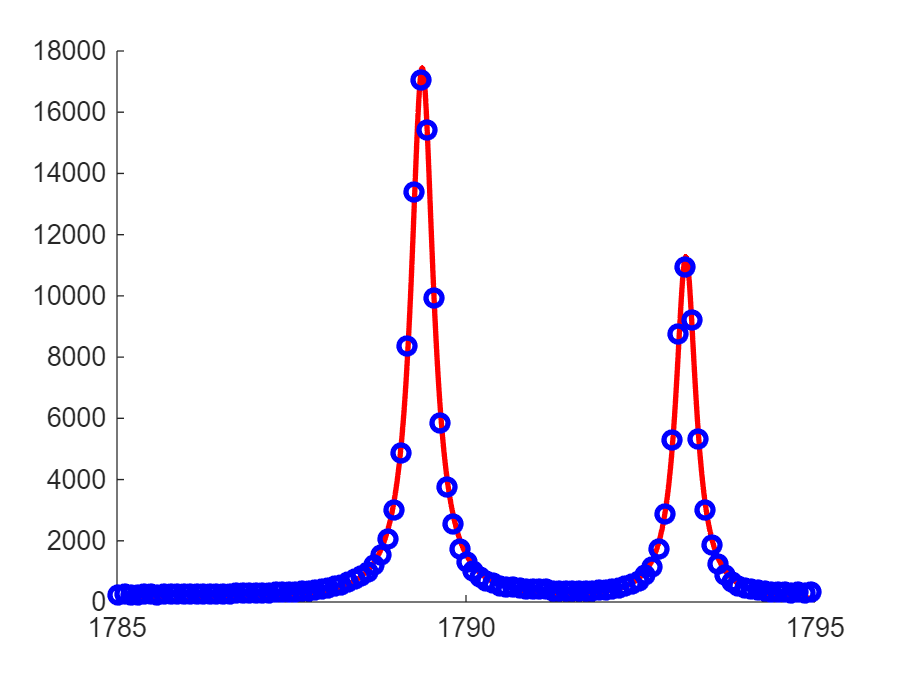

Temperature = 170 K


Loss = 23.6


I0 = 3385


d_{20}/d_{10} = 0.8657


Linewidths = [0.3885, 0.3488]


Delta = 3.777


E1 = 1789


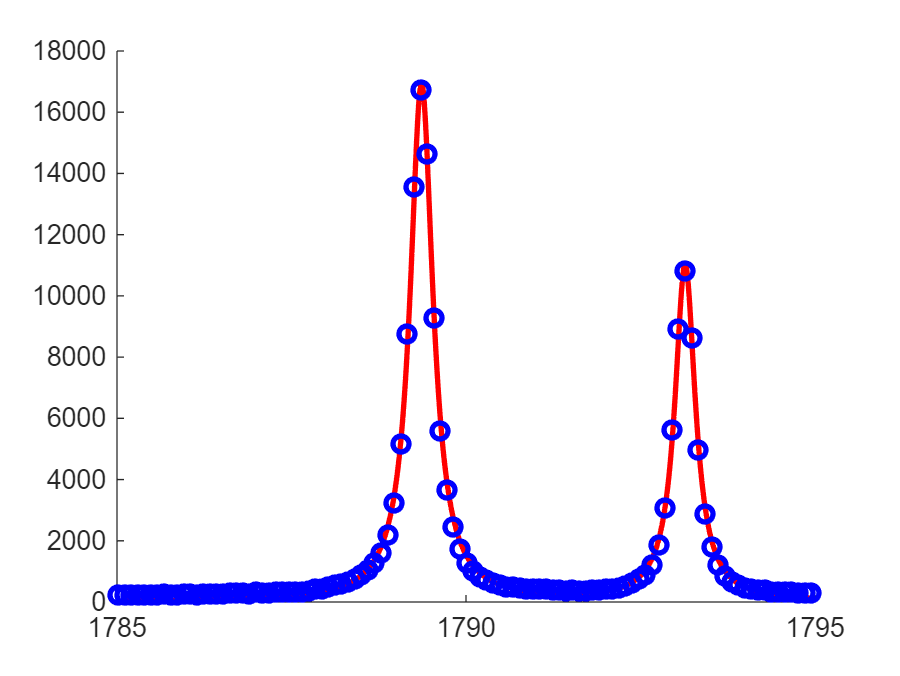

Temperature = 180 K


Loss = 21.36


I0 = 3364


d_{20}/d_{10} = 0.8608


Linewidths = [0.3977, 0.3558]


Delta = 3.776


E1 = 1789


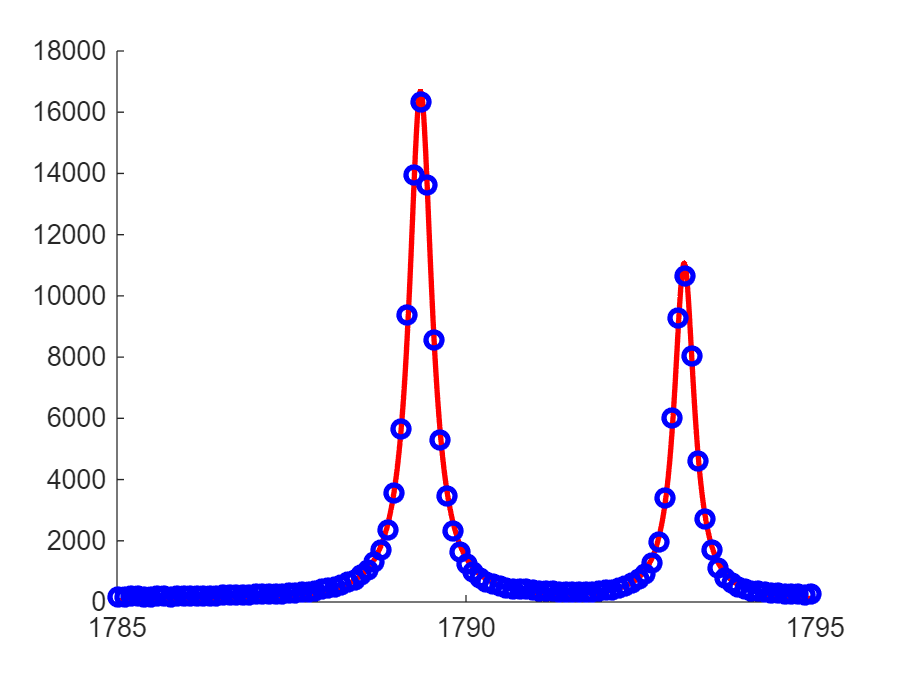

Temperature = 190 K


Loss = 7.19


I0 = 3308


d_{20}/d_{10} = 0.8546


Linewidths = [0.3968, 0.3478]


Delta = 3.777


E1 = 1789


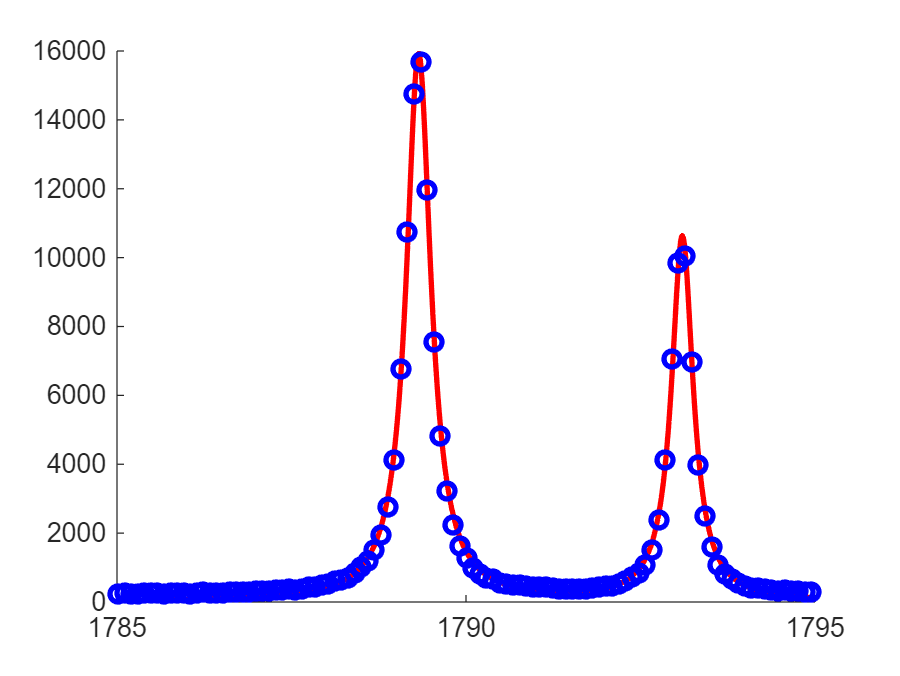

Temperature = 200 K


Loss = 21.98


I0 = 3400


d_{20}/d_{10} = 0.8534


Linewidths = [0.4274, 0.3756]


Delta = 3.778


E1 = 1789


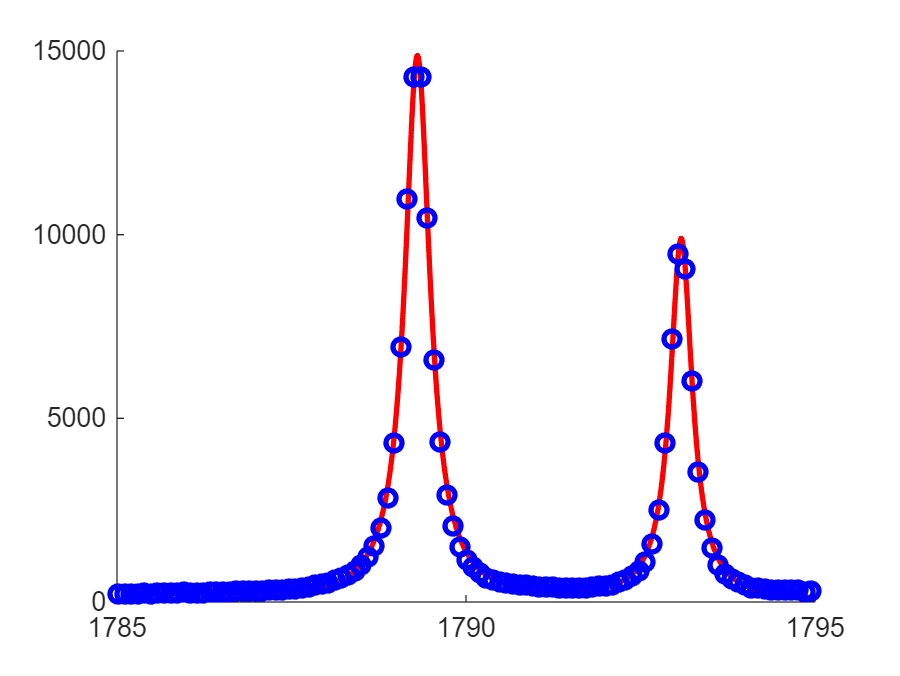

Temperature = 210 K


Loss = 20.05


I0 = 3253


d_{20}/d_{10} = 0.8468


Linewidths = [0.4379, 0.3841]


Delta = 3.779


E1 = 1789


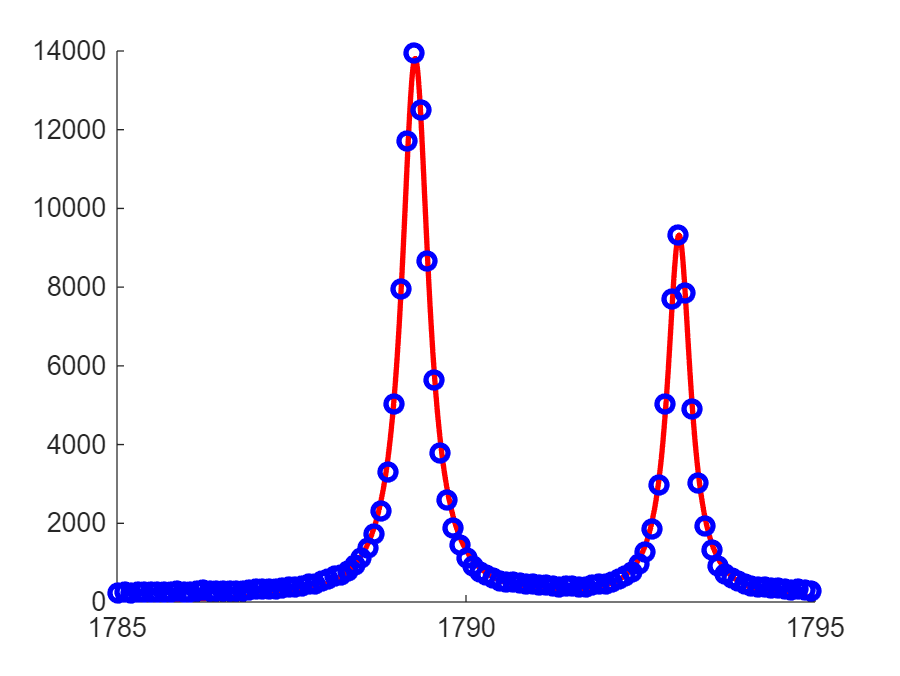

Temperature = 220 K


Loss = 25.05


I0 = 3214


d_{20}/d_{10} = 0.8429


Linewidths = [0.4661, 0.4033]


Delta = 3.781


E1 = 1789


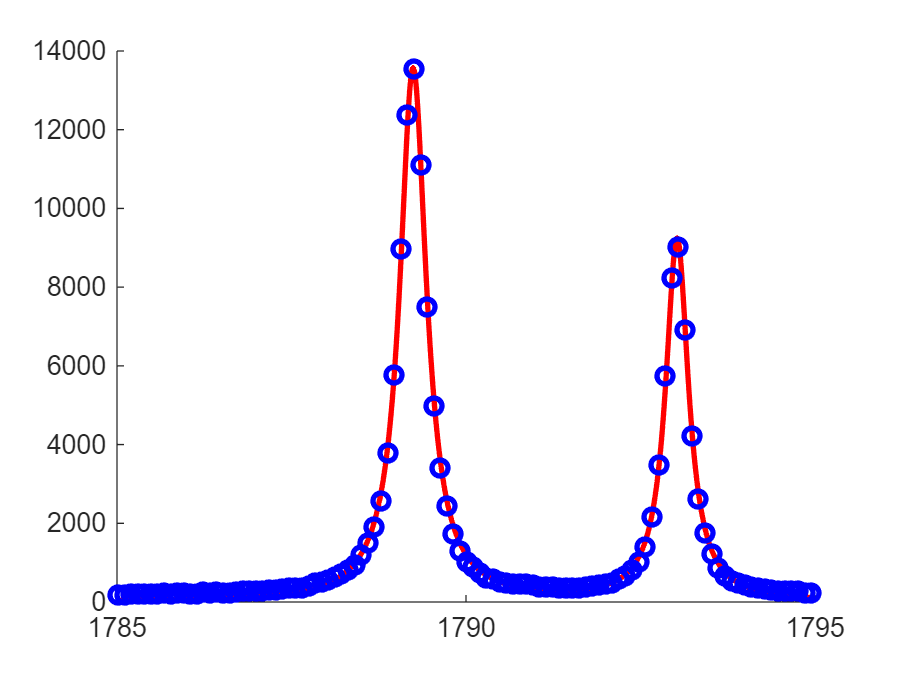

Temperature = 230 K


Loss = 8.6


I0 = 3151


d_{20}/d_{10} = 0.8388


Linewidths = [0.4652, 0.3981]


Delta = 3.782


E1 = 1789


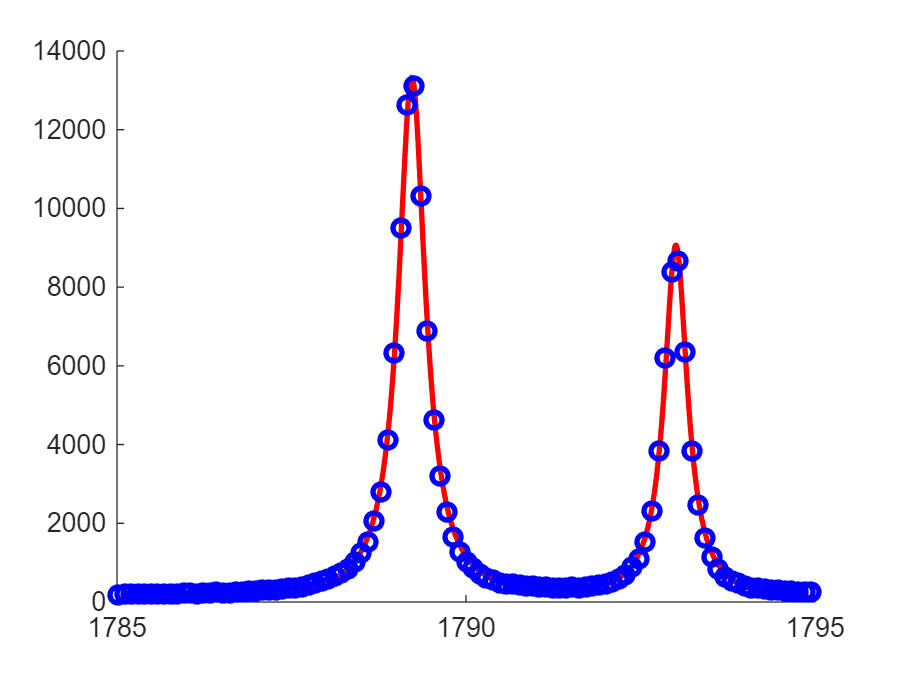

Temperature = 240 K


Loss = 7.995


I0 = 3140


d_{20}/d_{10} = 0.8356


Linewidths = [0.4718, 0.4049]


Delta = 3.783


E1 = 1789


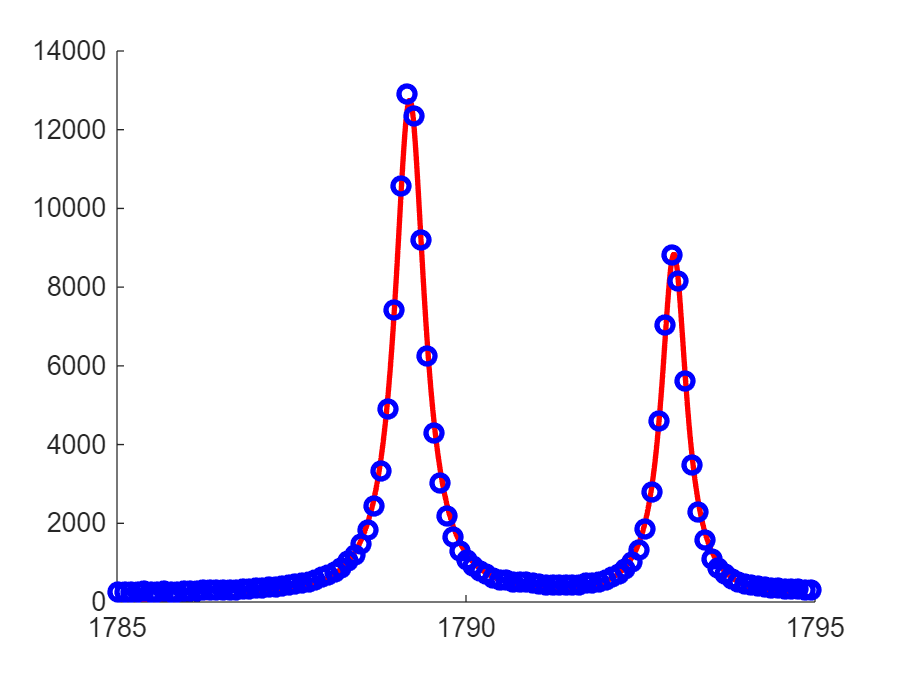

Temperature = 250 K


Loss = 26.73


I0 = 3302


d_{20}/d_{10} = 0.8354


Linewidths = [0.519, 0.4403]


Delta = 3.785


E1 = 1789


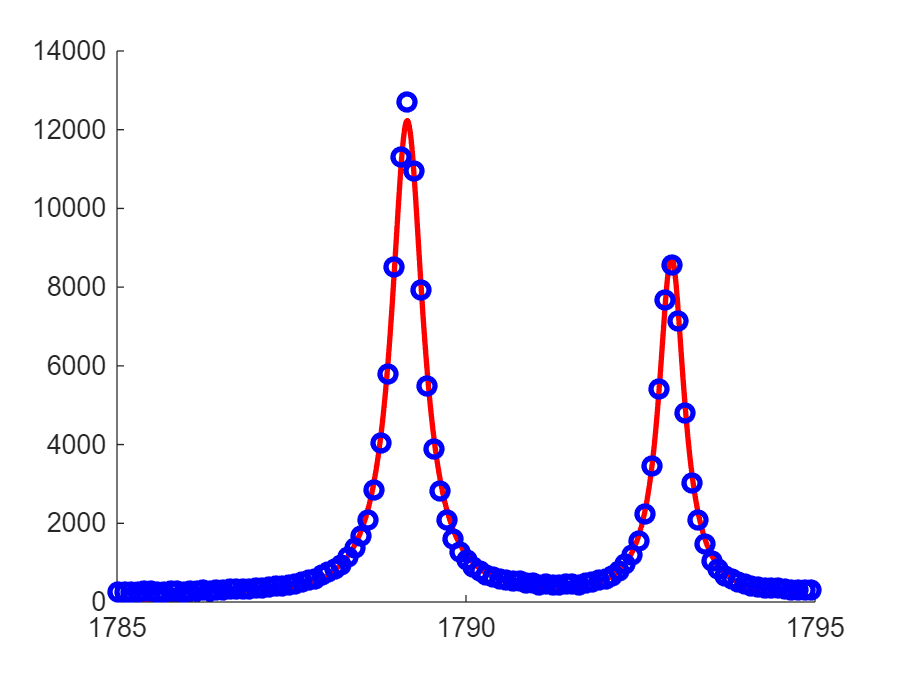

Temperature = 260 K


Loss = 22.84


I0 = 3339


d_{20}/d_{10} = 0.83


Linewidths = [0.5472, 0.4467]


Delta = 3.786


E1 = 1789


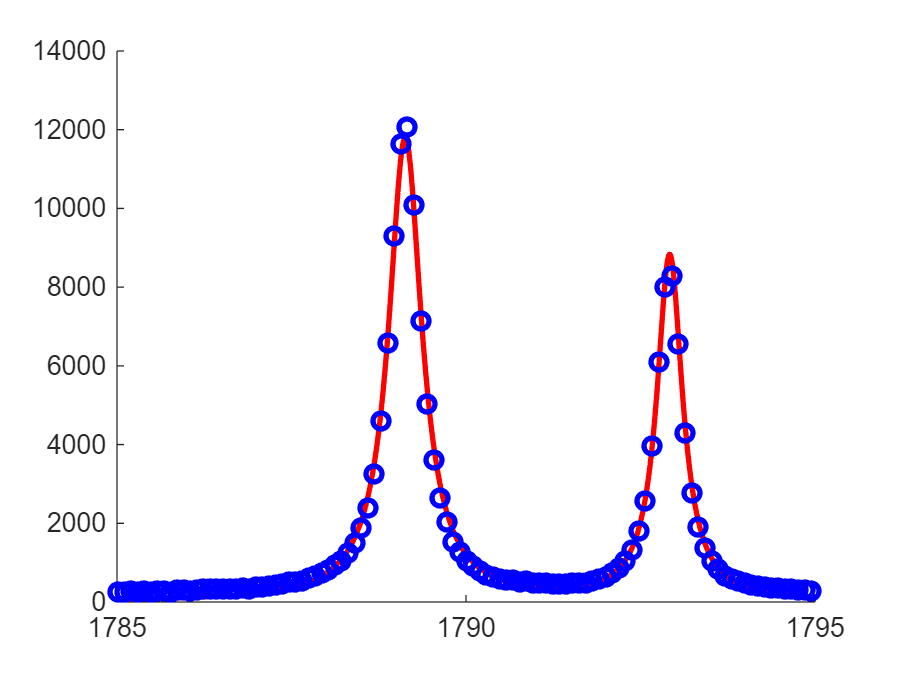

Temperature = 270 K


Loss = 27.09


I0 = 3398


d_{20}/d_{10} = 0.8238


Linewidths = [0.5773, 0.4467]


Delta = 3.789


E1 = 1789


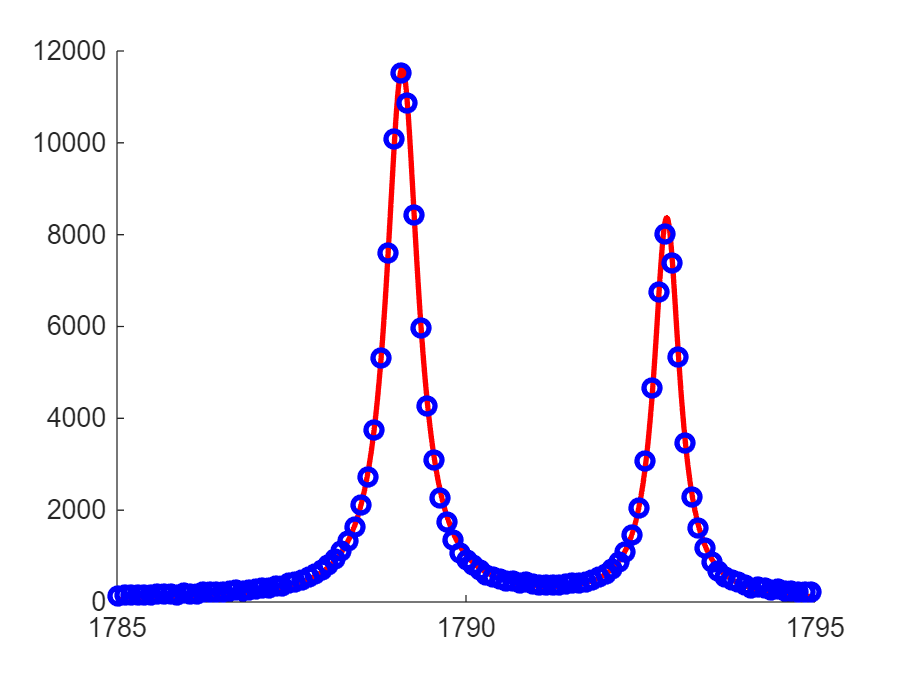

Temperature = 280 K


Loss = 2.582


I0 = 3213


d_{20}/d_{10} = 0.8221


Linewidths = [0.554, 0.4467]


Delta = 3.79


E1 = 1789


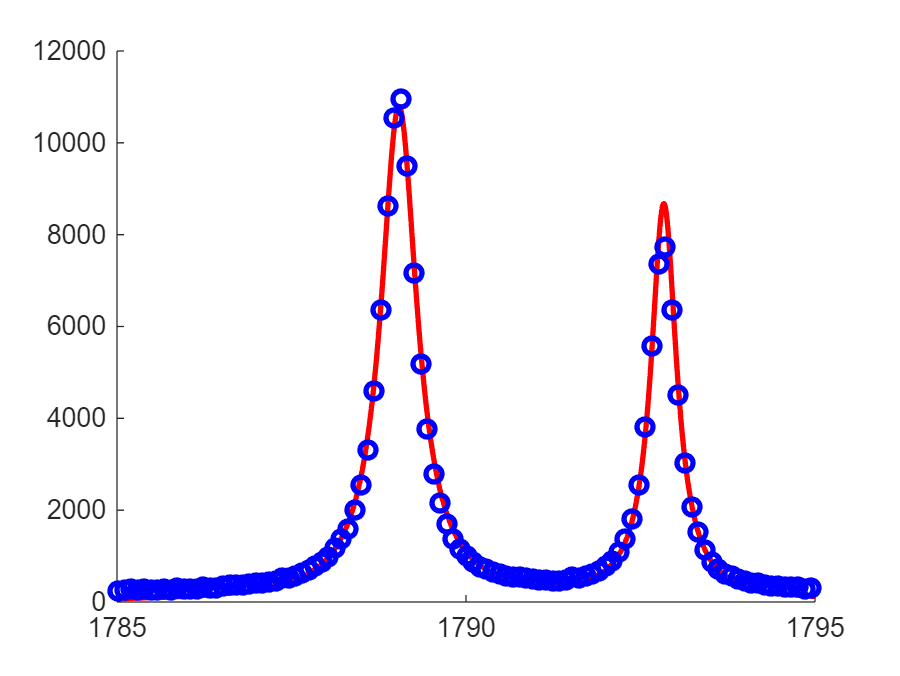

Temperature = 290 K


Loss = 26.43


I0 = 3396


d_{20}/d_{10} = 0.8116


Linewidths = [0.631, 0.4467]


Delta = 3.795


E1 = 1789


% photon energy range
Erange = [1785, 1795];
Energy = linspace(Erange(1), Erange(2), 1000);

% lower and upper bounds of fitting parameters
LowerBound = [2000, 0.5, -0.9, -0.8, 3.5, 1785];
UpperBound = [3400, 3, -0.2, -0.35, 4, 1795];

% fit all 29 data
for Dnum = 1:29
    T = 10*Dnum;    % temperature
    
    % choose data near the peaks
    Idx = RubyData{Dnum}(:,1) > Erange(1) & RubyData{Dnum}(:,1) < Erange(2);
    E_data = RubyData{Dnum}(Idx,1);
    I_data = RubyData{Dnum}(Idx,2);
    
    % make parameter bounds and loss function into a single struct variable
    options.lb = LowerBound;
    options.ub = UpperBound;
    options.loss_type = loss_func;
    
    % define fitting curve
    FitModel = @(Params, Energies) Spec_4lev(Params(1), Params(2), [power(10, Params(3)), power(10, Params(4))], Params(5), Params(6), T, Energies);
    
    % iterate to find best fit
    best_loss = Inf;
    for it = 1:3
        options.rng_seed = it;          % Try different seeds
        Params0 = rand(1,6) .* (UpperBound - LowerBound) + LowerBound;      % try different initial parameters
        [params_i, loss_hist_i] = de_curve_fit(FitModel, E_data, I_data, Params0, options);     % differential evolution fitting
        if loss_hist_i(end) < best_loss
            best_loss = loss_hist_i(end);
            FitParams = params_i;
            loss_history = loss_hist_i;
        end
    end
    
    I0 = FitParams(1);
    TransAmpR = FitParams(2);
    Linewidth = [power(10, FitParams(3)), power(10, FitParams(4))];
    Delta = FitParams(5);
    E1 = FitParams(6);
    
    % plot
    figure;
    hold on;
    I_fit = Spec_4lev(I0, TransAmpR, Linewidth, Delta, E1, T, Energy);
    plot(Energy, I_fit, 'color', 'red', 'LineWidth', 2);
    plot(E_data, I_data, 'o', 'color', 'blue', 'LineWidth', 2);
    hold off;
    
    % show fitted parameters
    disp(['Temperature = ', sprintf('%d', T), ' K']);
    disp(['Loss = ', sprintf('%.4g', best_loss)]);
    disp(['I0 = ', sprintf('%.4g', I0)]);
    disp(['d_{20}/d_{10} = ', sprintf('%.4g', TransAmpR)]);
    disp(['Linewidths = [', sprintf('%.4g', Linewidth(1)), ', ', sprintf('%.4g', Linewidth(2)) ']']);
    disp(['Delta = ', sprintf('%.4g', Delta)]);
    disp(['E1 = ', sprintf('%.4g', E1)]);
end